# Exam drill

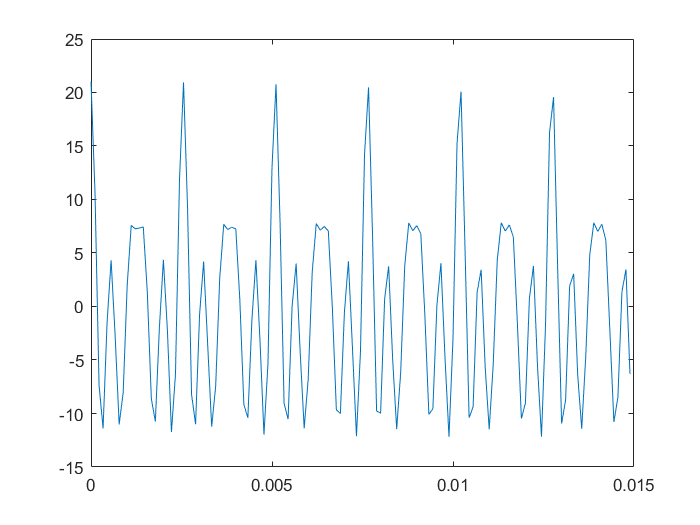

% Analog frequencies.
fa1 = 785;
fa2 = 2 * fa1;
fa3 = 2.5 * fa1;

A = 7;                      % Amplitude.
fs = 9e3;                   % Sampling frequency.
n = 0 : (0.25 * fs) - 1;    % Discrete time.

% Generate the three tones.
x1 = A * cos(2 * pi * fa1 / fs * n);
x2 = A * cos(2 * pi * fa2 / fs * n);
x3 = A * cos(2 * pi * fa3 / fs * n);

% Generamos la señal resultante de sumar los tres tonos
x = x1 + x2 + x3;

N = 0.015 * fs;     % Number of samples.
n_frag = 0 : N - 1; % Discrete time vector for the fragment.

% Plot the first 15 ms in the time domain.
t = n_frag / fs;
plot(t, x(1 : N));

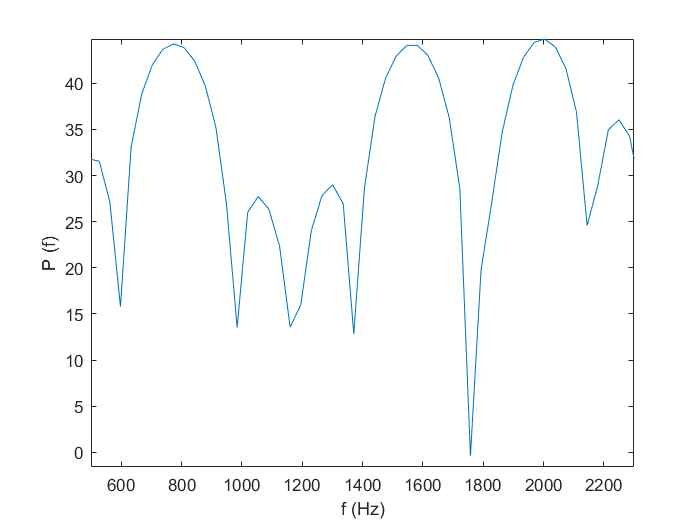


% Rectangular window.
% NOTE: we use digital frequencies.
L = round(2 * (1 / (fa3 / fs - fa2 / fs)));
rect = 1 : L;
x_rect = x(1 : L);

% Compute the spectrum.
N1 = 256;                                         % Number of points.
spectrum1 = fft(x_rect, N1);                      % Compute FFT.
spectrumShifted1 = fftshift(spectrum1);           % Shift spectrum to the origin.

N2 = 2048;
spectrum2 = fft(x_rect, N2);
spectrumShifted2 = fftshift(spectrum2);

% Logarithmic plot of the spectrum (magnitude).
f1 = (0 : (N1 - 1)) / N1 - 0.5;
plot(f1 * fs, 20 * log10(abs(spectrumShifted1)));
axis([500 2300 -inf inf])
ylabel('P (f)'), xlabel('f (Hz)');

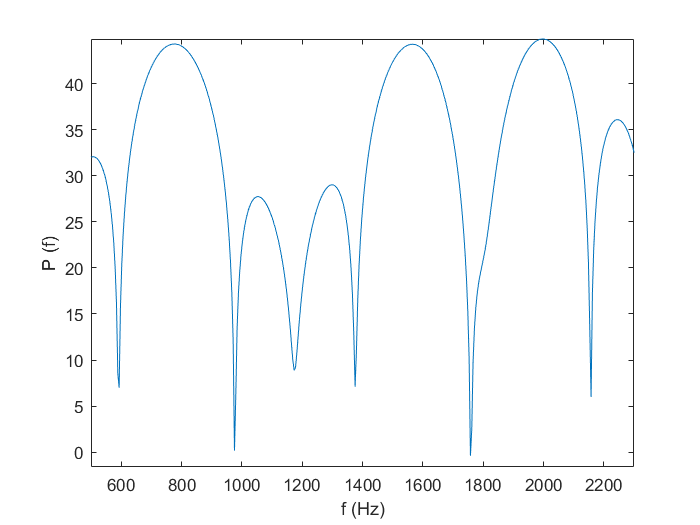


f2 = (0 : (N2 - 1)) / N2 - 0.5;
plot(f2 * fs, 20 * log10(abs(spectrumShifted2)));
ylabel('P (f)'), xlabel('f (Hz)');
axis([500 2300 -inf inf])